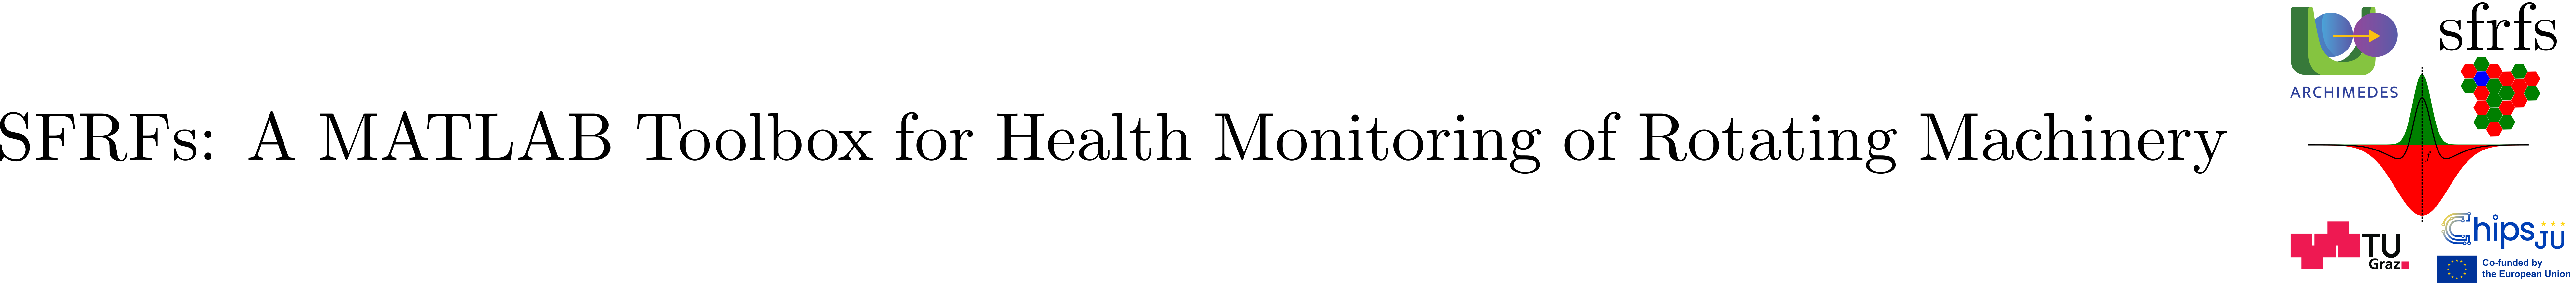

# SFRFsParametersRollingBearings

## Summary

Concrete subclass of `SFRFsParameters` dedicated to storing and validating Spectral Fault Receptive Field (SFRF) parameters for rolling bearing fault types.

Key features:

- Stores distinct validated SFRF parameter sets for four common bearing fault types: outer race (BPFO), inner race (BPFI), ball (BSF), and cage (FTF).

- Supports two construction modes: 

- Individual parameter structs for each fault type.

- A shared parameter struct applied to all fault types with enforceable consistency rules.

- Validates completeness of parameters and enforces domain-specific constraints, such as zero sidebands for outer race and cage faults.

- Provides constant fault type names and a collective list for ease of reference and validation.

- Includes detailed input argument validation with informative errors for missing or conflicting parameter sets.

- Implements a `toString` method returning a JSON-like formatted summary of all fault type parameters for logging and diagnostics.

This value class is essential for precise and consistent parameterization of bearing fault receptive field modeling within the SFRF framework.

## Description

SFRFsParametersRollingBearings is a concrete subclass of [SFRFsParameters](matlab:open('./SFRFsParameters.mlx')) that defines the parameter organization used to construct Spectral Fault Receptive Fields (SFRFs) for rolling bearing diagnosis. The class provides a validated and domain-specific grouping of SFRF parameter sets for the four canonical bearing fault modes: outer race (BPFO), inner race (BPFI), ball (BSF), and cage (FTF). Each fault type is represented by its own parameter struct, adhering to the standardized SFRF field names defined in the superclass.

The class supports two construction modes. In the first mode, users specify individual SFRF parameter sets per fault type, enabling fine-grained tailoring of receptive-field configurations to each spectral signature. In the second mode, a single shared parameter set may be applied across all fault types through the SameForAllFaultTypes argument. In this shared mode, the class automatically enforces domain constraints by forcing the outer race and cage fault types to use zero sidebands.

SFRFsParametersRollingBearings performs comprehensive validation of constructor inputs, ensuring that all required SFRF fields are present and that constraints specific to bearing faults are respected. Missing or inconsistent configurations raise descriptive diagnostic errors, facilitating reliable integration within larger processing pipelines.

The class exposes the four validated parameter groups through its public properties: outerRace, innerRace, ball, and cage, each containing a complete SFRF parameter struct constructed using the factory method of the superclass. A formatted textual representation is provided through the toString method, supporting structured logging and debugging.

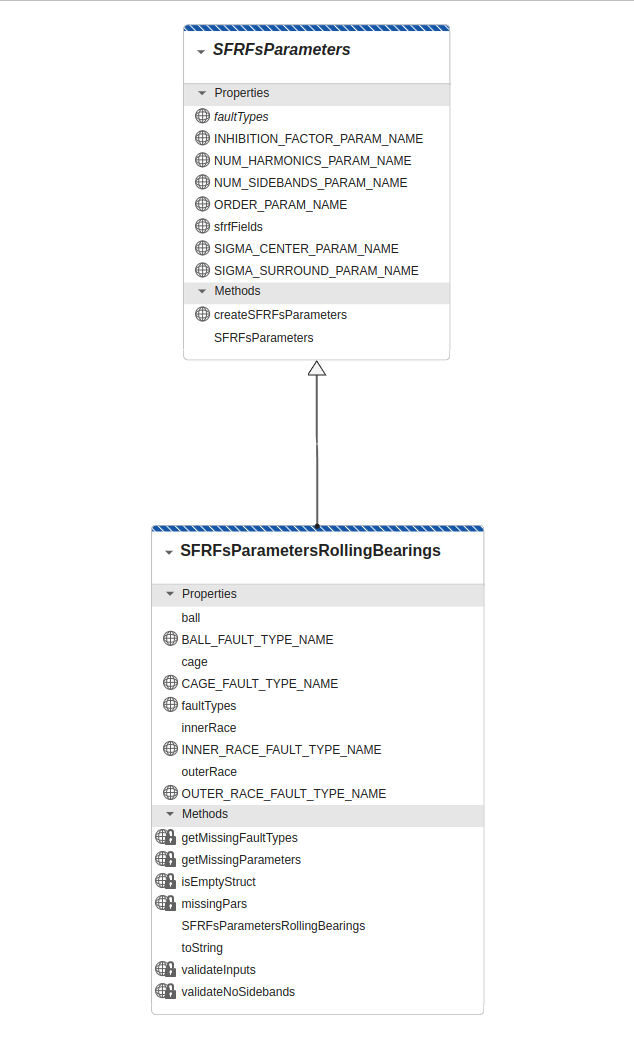

**Figure 1**. SFRFsParametersRollingBearings extends SFRFsParameters.

Figure 1 shows SFRFsParametersRollingBearings implements the abstract members of its parent class, that is, it provides the list of relevant fault modes concretizing the attribute `faultypes`. This same list corresponds with the added attributes: `ball`, `cage`, `innerRace`, and `outerRace `that will store `struct` objects as created by the method `SFRFsParameters.createSFRFsParameters.`

### Constant properties (concrete from abstract inherited)

### Properties

For more details on the 4 fault modes see Reference [1] and MATLAB [`bearingFaultBands`](https://www.mathworks.com/help/predmaint/ref/bearingfaultbands.html) function in the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html?utm_source=chatgpt.com).

### Constructor

`SFRFsParametersRollingBearings(parameter=value, ...)`

Constructs and validates parameter sets for the four supported bearing fault modes. Two construction patterns are supported:

- **Individual parameter sets per fault type**. Each of the four parameters (outerRace, innerRace, ball, cage) is provided independently.

- **Shared parameter set for all fault types**A single struct is supplied via **SameForAllFaultTypes**, and applied to all fault modes.In this mode, the constructor **automatically** sets `numSidebands = 0` for outerRace and cage to satisfy the domain constraint that these modes do not include sideband structures.

The constructor verifies:

- that conflicting combinations of arguments are not used

- that all required SFRF fields are present

- that no fault type is left unspecified

- that outer race and cage parameter sets contain zero sidebands

- that shared parameters contain all required fields before they are replicated

Invalid configurations result in descriptive errors summarizing missing fields or conflicting arguments.

### String representation

`toString() method r`eturns a formatted, JSON-encoded summary of the four SFRF parameter groups.

This representation is used by `SFRFsLogger` when fine-level logging is enabled, assisting in debugging and traceability.

## Example

The parameters shown in the example are illustrative only and not intended to be meaningful. A detail explanation can be found in [SFRFsParameters](matlab:open('./SFRFsParameters.mlx')).

### Individual parameters especification

% Individual SFRF parameters per fault type
% Parameters for outer race faults
paramsOuter = ...
    SFRFsParameters.createSFRFsParameters(...
    order = 2, ...
    numSidebands = 0, ...
    sigmaCenter = [5,7], ...
    inhibitionFactor = 0.2);
disp(paramsOuter);

               order: 2
        numSidebands: 0
        numHarmonics: 10
         sigmaCenter: [5 7]
       sigmaSurround: [12 1]
    inhibitionFactor: 0.2000




% Parameters for inner race faults
paramsInner = ...
    SFRFsParameters.createSFRFsParameters(...
    order = 1, ...
    numHarmonics = 8);
disp(paramsInner);

               order: 1
        numSidebands: 2
        numHarmonics: 8
         sigmaCenter: [4 6]
       sigmaSurround: [12 1]
    inhibitionFactor: 0.8000




% Parameters for rolling elements
paramsBall  = ...
    SFRFsParameters.createSFRFsParameters(...
    order=0, ...
    sigmaCenter = [4,6]);
disp(paramsBall);

               order: 0
        numSidebands: 2
        numHarmonics: 10
         sigmaCenter: [4 6]
       sigmaSurround: [12 1]
    inhibitionFactor: 0.8000




% Parameters for cage faults
paramsCage  = ...
    SFRFsParameters.createSFRFsParameters( ...
    numSidebands = 0);
disp(paramsCage);

               order: 0
        numSidebands: 0
        numHarmonics: 10
         sigmaCenter: [4 6]
       sigmaSurround: [12 1]
    inhibitionFactor: 0.8000




params = SFRFsParametersRollingBearings( ...
    outerRace = paramsOuter, ...
    innerRace = paramsInner, ...
    ball = paramsBall, ...
    cage = paramsCage );
disp(params.toString());

[SFRFsParametersRollingBearings: outerRace: {"order":2,"numSidebands":0,"numHarmonics":10,"sigmaCenter":[5,7],"sigmaSurround":[12,1],"inhibitionFactor":0.2}, innerRace: {"order":1,"numSidebands":2,"numHarmonics":8,"sigmaCenter":[4,6],"sigmaSurround":[12,1],"inhibitionFactor":0.8}, ball: {"order":0,"numSidebands":2,"numHarmonics":10,"sigmaCenter":[4,6],"sigmaSurround":[12,1],"inhibitionFactor":0.8}, cage: {"order":0,"numSidebands":0,"numHarmonics":10,"sigmaCenter":[4,6],"sigmaSurround":[12,1],"inhibitionFactor":0.8}]


### All parameters equal

% Parameters for all types faults
params  = ...
    SFRFsParameters.createSFRFsParameters();
disp(params);

               order: 0
        numSidebands: 2
        numHarmonics: 10
         sigmaCenter: [4 6]
       sigmaSurround: [12 1]
    inhibitionFactor: 0.8000



params = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes=params);
disp(params.toString());

[SFRFsParametersRollingBearings: outerRace: {"order":0,"numSidebands":0,"numHarmonics":10,"sigmaCenter":[4,6],"sigmaSurround":[12,1],"inhibitionFactor":0.8}, innerRace: {"order":0,"numSidebands":2,"numHarmonics":10,"sigmaCenter":[4,6],"sigmaSurround":[12,1],"inhibitionFactor":0.8}, ball: {"order":0,"numSidebands":2,"numHarmonics":10,"sigmaCenter":[4,6],"sigmaSurround":[12,1],"inhibitionFactor":0.8}, cage: {"order":0,"numSidebands":0,"numHarmonics":10,"sigmaCenter":[4,6],"sigmaSurround":[12,1],"inhibitionFactor":0.8}]


In this case the number of sidebands is set to zero for outerRace and cage properties.

% displaying the parameter values for cage fault type
disp(params.cage)

               order: 0
        numSidebands: 0
        numHarmonics: 10
         sigmaCenter: [4 6]
       sigmaSurround: [12 1]
    inhibitionFactor: 0.8000



## API documentation

### MATLAB help

help SFRFsParametersRollingBearings

  SFRFsParametersRollingBearings  Store and validate SFRF parameters for 
  bearing fault types.
 
    This value class stores validated Spectral Fault Receptive Field (SFRF) 
    parameter sets for:
       - Outer race (BPFO frequency band)
       - Inner race (BPFI frequency band)
       - Ball       (BSF frequency band)
       - Cage       (FTF frequency band)
 
    Construction uses named (keyword) arguments and supports two modes:
 
    Mode 1: Individual SFRF parameters per fault type
      Mode 1 – Individual parameters for each fault type:
          paramsOuter = ...
            SFRFsParameters.createSFRFsParameters(...
            'order',2, 'sigmaCenter',[5,7]);
          paramsInner = ...
            SFRFsParameters.createSFRFsParameters(...
            'order',1, 'numHarmonics',8);
          paramsBall  = 
            SFRFsParameters.createSFRFsParameters(...
            'order',0, 'sigmaCenter',[4,6]);
          % use defaults
          paramsCage  = ...
            SFRFsP

### MATLAB documentation

doc SFRFsParametersRollingBearings

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source code for the class can be found in [SFRFsParametersRollingBearings](matlab:open('../../SFRFsParametersRollingBearings.m')).

## Test

Unit test for the class is implemented in [TestSFRFsParametersRollingBearings](matlab:open('../../../tests/TestSFRFsParametersRollingBearings.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestSFRFsParametersRollingBearings');

Running TestSFRFsParametersRollingBearings
.......... .
Done TestSFRFsParametersRollingBearings
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestSFRFsParametersRollingBearings/testMode1ValidConstruction                    | Passed
TestSFRFsParametersRollingBearings/testMode2ValidConstruction                    | Passed
TestSFRFsParametersRollingBearings/testMissingFieldsError                        | Passed
TestSFRFsParametersRollingBearings/testMutualExclusivityError                    | Passed
TestSFRFsParametersRollingBearings/testMissingFaultTypeError                     | Passed
TestSFRFsParametersRollingBearings/testOrderValidation                           | Passed
TestSFRFsParametersRollingBearings/testNumSidebandsValidation                    | Passed
TestSFRFsParametersRollingBearings/testNumHarmonicsValidation                    | Passed
TestSFRFsParametersRollingBearings/testSigmaCenterValidation                     | Passed
TestSFRFsP

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).